% FİNAL İÇİN TEKRAR

%SORU 1
xler = [2 1 -1; 5 -3 -3; 1 2 1]

xler =      2     1    -1
     5    -3    -3
     1     2     1


yler = [6;5;3]

yler =      6
     5
     3


cozum = xler\yler

cozum =      1
     2
    -2


disp(cozum)

     1
     2
    -2



disp('--------------------------------------------------------------')

--------------------------------------------------------------



%SORU 2: y = 3x + 5 ve y = -x + 3 doğrularını x = (-4,4) aralığında çiziniz
x1_1 = -4

x1_1 = -4

y1_1 = 3*x1_1 +5

y1_1 = -7


x1_2 = 4

x1_2 = 4

y1_2 = 3*x1_2 + 5

y1_2 = 17

line([x1_1 x1_2], [y1_1 y1_2])

x2_1 = 4

x2_1 = 4

y2_1 = -x2_1 + 3

y2_1 = -1


x2_2 = -4

x2_2 = -4

y2_2 = -x2_2 + 3

y2_2 = 7

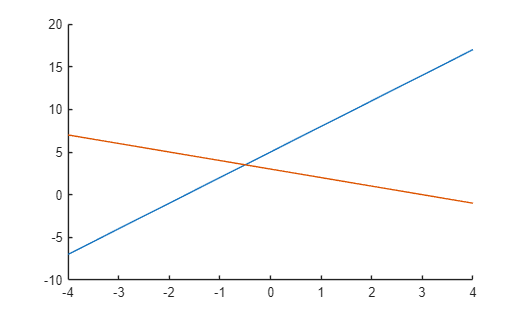

line([x2_1 x2_2],[y2_1 y2_2])

disp('--------------------------------------------------------------')

--------------------------------------------------------------


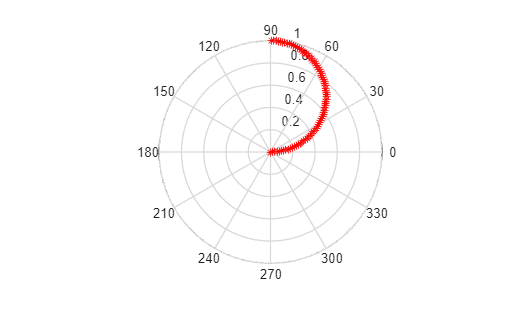


%SORU 3: Açı 0 dan 90 dereceye kadar 0.02 radyan artımıyla değişirken her
%adım için modül açının sinüsü olarak seçiliyor. Eğri * sembollerini
%kullanarak kırmızı renkle oluşturunuz.

t1 = 0:0.02:pi/2;
polar(t1,sin(t1),'*r')

disp('--------------------------------------------------------------')

--------------------------------------------------------------


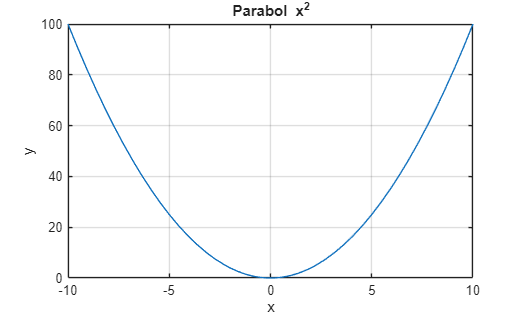


%SORU 4: y = x^2 parabolünü x = (-10,10), y = (-100,100) aralığındaki
%grafiğini çiziniz

fplot(@(x) x.^2,[-10 10])
grid on
xlabel('x')
ylabel('y')
title('Parabol x^2')

disp('--------------------------------------------------------------')

--------------------------------------------------------------


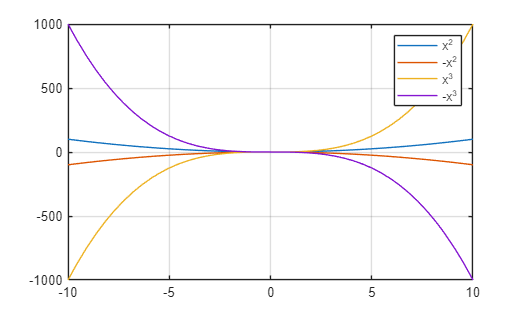


%SORU 5: x^2, -x^2, x^3, -x^3 parabollerinin grafiklerini çiziniz
figure(1)
fplot(@(x)[x.^2,-x.^2,x.^3,-x.^3],[-10 10])
grid on
legend('x^2','-x^2','x^3','-x^3')



disp('--------------------------------------------------------------')

--------------------------------------------------------------



%SORU 6: b=2,3 c=4,7 noktaları arasına çizilecek doğru parçasını saat yönü
%tersine 90 derece çeviriniz

figure(2)
line([0 0],[-10 10])
line([-10 10],[0 0])
line([2 4],[3 7])
B = [2,3]

B =      2     3


C = [4,7]

C =      4     7


A = [0 -1;1 0]

A =      0    -1
     1     0


bTers = A*B'

bTers =     -3
     2


cTers = A*C'

cTers =     -7
     4


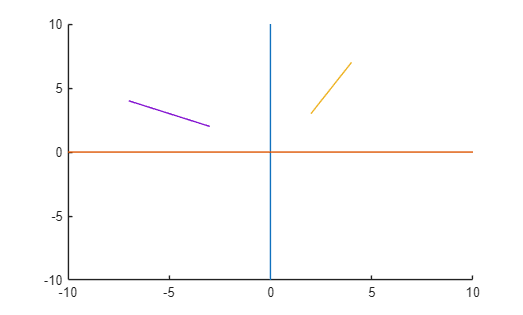

line([bTers(1) cTers(1)],[bTers(2) cTers(2)])


disp('--------------------------------------------------------------')

--------------------------------------------------------------



%SORU 7: fx = 2x^3 -7x + 3/2 fonksiyonunun (2,3.5) noktasındaki teğetini
%bul ve grafiğini çiz

figure(3)
syms x
f = 2*x^3 - 7*x + 3/2;
df = diff(f,x);

fTeget = subs(df,x,2)

$$fTeget = 17$$


sabit = 3.5 - fTeget * 2

$$sabit = -\frac{61}{2}$$

yT = fTeget * x + sabit

$$yT = 17\,x-\frac{61}{2}$$

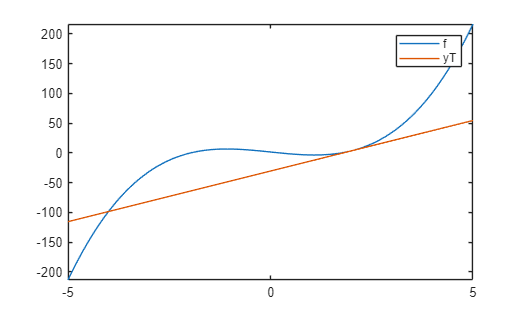


fplot(f)
hold on
fplot(yT)
legend('f','yT')